clc; clear all; close all;

syms phi theta phi_dot theta_dot phi_ddot theta_ddot phi_ref theta_ref
syms t tau
syms l_p l_w m_w m_p g k_phi k_theta d_theta d_phi x x_ddot x_dot J_p J_w d_thetadot d_phidot 


generalized coordinates and angles

q = [theta; phi], qdot =[theta_dot; phi_dot] , qddot = [theta_ddot; phi_ddot]

$$q = \left(\begin{array}{c} \theta \\ \varphi \end{array}\right)$$

$$qdot = \left(\begin{array}{c} \dot{\theta }\\ \dot{\varphi } \end{array}\right)$$

$$qddot = \left(\begin{array}{c} \ddot{\theta }\\ \ddot{\varphi } \end{array}\right)$$

w_angle = [0;0;theta+phi], p_angle = [0;0;theta]

$$w\_angle = \left(\begin{array}{c} 0\\ 0\\ \varphi +\theta \end{array}\right)$$

$$p\_angle = \left(\begin{array}{c} 0\\ 0\\ \theta \end{array}\right)$$

## Question A

Express the position ri and velocity ˙ri vector for points i = 2, and i = 3 in terms of the variables θ, ϕ, x, and the system parameters.

r1 = [x;0;0], r2 = [x + l_w*cos(theta); l_w*sin(theta);0], r3 = [x - l_p*cos(theta); l_p*sin(theta);0]

$$r1 = \left(\begin{array}{c} x\\ 0\\ 0 \end{array}\right)$$

$$r2 = \left(\begin{array}{c} x+l_{w}\,\cos\left(\theta \right)\\ l_{w}\,\sin\left(\theta \right)\\ 0 \end{array}\right)$$

$$r3 = \left(\begin{array}{c} x-l_{p}\,\cos\left(\theta \right)\\ l_{p}\,\sin\left(\theta \right)\\ 0 \end{array}\right)$$


r1_dot = [x_dot;0;0] , r2_dot = jacobian(r2,q)*qdot+r1_dot, r3_dot = jacobian(r3,q)*qdot+r1_dot

$$r1\_dot = \left(\begin{array}{c} \dot{x}\\ 0\\ 0 \end{array}\right)$$

$$r2\_dot = \left(\begin{array}{c} \dot{x}-l_{w}\,\dot{\theta }\,\sin\left(\theta \right)\\ l_{w}\,\dot{\theta }\,\cos\left(\theta \right)\\ 0 \end{array}\right)$$

$$r3\_dot = \left(\begin{array}{c} \dot{x}+l_{p}\,\dot{\theta }\,\sin\left(\theta \right)\\ l_{p}\,\dot{\theta }\,\cos\left(\theta \right)\\ 0 \end{array}\right)$$

## Question B

Express the kinetic energy T in terms of the variables θ, ϕ, x, and the system parameters. 

T2 = simplify(1/2*m_w*r2_dot.'*r2_dot+1/2*J_w*(phi_dot+theta_dot)^2), T3 = simplify(1/2*m_p*r3_dot.'*r3_dot + 1/2*J_p*theta_dot^2)

$$T2 = \frac{m_{w}\,{\left(\dot{x}-l_{w}\,\dot{\theta }\,\sin\left(\theta \right)\right)}^{2}}{2}+\frac{J_{w}\,{\left(\dot{\varphi }+\dot{\theta }\right)}^{2}}{2}+\frac{{l_{w}}^{2}\,m_{w}\,{\dot{\theta }}^{2}\,{\cos\left(\theta \right)}^{2}}{2}$$

$$T3 = \frac{m_{p}\,{l_{p}}^{2}\,{\dot{\theta }}^{2}}{2}+m_{p}\,\sin\left(\theta \right)\,l_{p}\,\dot{\theta }\,\dot{x}+\frac{J_{p}\,{\dot{\theta }}^{2}}{2}+\frac{m_{p}\,{\dot{x}}^{2}}{2}$$

T = simplify(T2+T3)

$$T = \frac{m_{w}\,{\left(\dot{x}-l_{w}\,\dot{\theta }\,\sin\left(\theta \right)\right)}^{2}}{2}+\frac{J_{w}\,{\left(\dot{\varphi }+\dot{\theta }\right)}^{2}}{2}+\frac{J_{p}\,{\dot{\theta }}^{2}}{2}+\frac{m_{p}\,{\dot{x}}^{2}}{2}+\frac{{l_{p}}^{2}\,m_{p}\,{\dot{\theta }}^{2}}{2}+\frac{{l_{w}}^{2}\,m_{w}\,{\dot{\theta }}^{2}\,{\cos\left(\theta \right)}^{2}}{2}+l_{p}\,m_{p}\,\dot{\theta }\,\dot{x}\,\sin\left(\theta \right)$$

## Question C

Express the potential energy V in terms of the variables θ, ϕ, x, and the system parameters. Define the potential energy such that V = 0 on the (global) x-axis.

Uk = 1/2*k_theta*(theta-theta_ref)^2 + 1/2*k_phi*(phi-phi_ref)^2

$$Uk = \frac{k_{\varphi }\,{\left(\varphi -\varphi_{\mathrm{ref}}\right)}^{2}}{2}+\frac{k_{\theta }\,{\left(\theta -\theta_{\mathrm{ref}}\right)}^{2}}{2}$$

Vg = m_p * g * l_p * sin(theta) + m_w * g * l_w * sin(theta)

$$Vg = g\,l_{p}\,m_{p}\,\sin\left(\theta \right)+g\,l_{w}\,m_{w}\,\sin\left(\theta \right)$$


V = Uk + Vg

$$V = \frac{k_{\varphi }\,{\left(\varphi -\varphi_{\mathrm{ref}}\right)}^{2}}{2}+\frac{k_{\theta }\,{\left(\theta -\theta_{\mathrm{ref}}\right)}^{2}}{2}+g\,l_{p}\,m_{p}\,\sin\left(\theta \right)+g\,l_{w}\,m_{w}\,\sin\left(\theta \right)$$

## Question D

Express the generalized forces Qnc that follow from the non-conservative forces acting on the system in terms of the variables θ, ϕ, τ, x, and the system parameters. Hint: Remember to take all non-conservative forces into account. The motor will induce a torque and a counter torque.

M2 = [0;0;tau - d_phi*phi_dot], M3 = [0;0;d_phi*phi_dot-tau - d_theta*theta_dot]

$$M2 = \left(\begin{array}{c} 0\\ 0\\ \tau -d_{\varphi }\,\dot{\varphi } \end{array}\right)$$

$$M3 = \left(\begin{array}{c} 0\\ 0\\ d_{\varphi }\,\dot{\varphi }-\tau -d_{\theta }\,\dot{\theta } \end{array}\right)$$

jacobian(w_angle,q)

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

jacobian(p_angle,q)

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

Q2 = jacobian(w_angle,q).'*M2, Q3 = jacobian(p_angle,q).'*M3

$$Q2 = \left(\begin{array}{c} \tau -d_{\varphi }\,\dot{\varphi }\\ \tau -d_{\varphi }\,\dot{\varphi } \end{array}\right)$$

$$Q3 = \left(\begin{array}{c} d_{\varphi }\,\dot{\varphi }-\tau -d_{\theta }\,\dot{\theta }\\ 0 \end{array}\right)$$


Q = simplify(Q2+Q3)

$$Q = \left(\begin{array}{c} -d_{\theta }\,\dot{\theta }\\ \tau -d_{\varphi }\,\dot{\varphi } \end{array}\right)$$

## Question E

Compute the parametric (i.e., do not fill in the parameter values!) Equations of Motion (EoMs) using T, V and Q nc as determined in the previous exercises. Simplify each EoM as much as possible and rewrite each EOM ensuring that a zero appears on the right side of the equal sign.

L = simplify (T-V)

$$L = \frac{m_{w}\,{\left(\dot{x}-l_{w}\,\dot{\theta }\,\sin\left(\theta \right)\right)}^{2}}{2}+\frac{J_{w}\,{\left(\dot{\varphi }+\dot{\theta }\right)}^{2}}{2}+\frac{J_{p}\,{\dot{\theta }}^{2}}{2}+\frac{m_{p}\,{\dot{x}}^{2}}{2}-\frac{k_{\varphi }\,{\left(\varphi -\varphi_{\mathrm{ref}}\right)}^{2}}{2}-\frac{k_{\theta }\,{\left(\theta -\theta_{\mathrm{ref}}\right)}^{2}}{2}+\frac{{l_{p}}^{2}\,m_{p}\,{\dot{\theta }}^{2}}{2}-g\,l_{p}\,m_{p}\,\sin\left(\theta \right)-g\,l_{w}\,m_{w}\,\sin\left(\theta \right)+\frac{{l_{w}}^{2}\,m_{w}\,{\dot{\theta }}^{2}\,{\cos\left(\theta \right)}^{2}}{2}+l_{p}\,m_{p}\,\dot{\theta }\,\dot{x}\,\sin\left(\theta \right)$$

dL_dqdot = jacobian(L, qdot).';
dTdq_dot = jacobian(T,qdot);
d_dt_dL_dqdot = jacobian(dL_dqdot, q)*qdot + jacobian(dL_dqdot, qdot)*qddot + jacobian(dL_dqdot, x)*x_dot + jacobian(dL_dqdot, x_dot)*x_ddot;
dL_dq = jacobian(L, q).';

% Equations of Motion
EoM = simplify(d_dt_dL_dqdot - dL_dq - Q) 

$$EoM = \left(\begin{array}{c} J_{w}\,\ddot{\varphi }+J_{p}\,\ddot{\theta }+J_{w}\,\ddot{\theta }+d_{\theta }\,\dot{\theta }+k_{\theta }\,\theta -k_{\theta }\,\theta_{\mathrm{ref}}+{l_{p}}^{2}\,m_{p}\,\ddot{\theta }+{l_{w}}^{2}\,m_{w}\,\ddot{\theta }+g\,l_{p}\,m_{p}\,\cos\left(\theta \right)+g\,l_{w}\,m_{w}\,\cos\left(\theta \right)+l_{p}\,m_{p}\,\ddot{x}\,\sin\left(\theta \right)-l_{w}\,m_{w}\,\ddot{x}\,\sin\left(\theta \right)\\ J_{w}\,\ddot{\varphi }-\tau +J_{w}\,\ddot{\theta }+d_{\varphi }\,\dot{\varphi }+\frac{k_{\varphi }\,\left(2\,\varphi -2\,\varphi_{\mathrm{ref}}\right)}{2} \end{array}\right)$$

SimEoM = EoM == 0

$$SimEoM = \left(\begin{array}{c} J_{w}\,\ddot{\varphi }+J_{p}\,\ddot{\theta }+J_{w}\,\ddot{\theta }+d_{\theta }\,\dot{\theta }+k_{\theta }\,\theta -k_{\theta }\,\theta_{\mathrm{ref}}+{l_{p}}^{2}\,m_{p}\,\ddot{\theta }+{l_{w}}^{2}\,m_{w}\,\ddot{\theta }+g\,l_{p}\,m_{p}\,\cos\left(\theta \right)+g\,l_{w}\,m_{w}\,\cos\left(\theta \right)+l_{p}\,m_{p}\,\ddot{x}\,\sin\left(\theta \right)-l_{w}\,m_{w}\,\ddot{x}\,\sin\left(\theta \right)=0\\ J_{w}\,\ddot{\varphi }-\tau +J_{w}\,\ddot{\theta }+d_{\varphi }\,\dot{\varphi }+\frac{k_{\varphi }\,\left(2\,\varphi -2\,\varphi_{\mathrm{ref}}\right)}{2}=0 \end{array}\right)$$

## Question F

Mass_Matrix = jacobian(EoM, qddot)

$$Mass\_Matrix = \left(\begin{array}{cc} m_{p}\,{l_{p}}^{2}+m_{w}\,{l_{w}}^{2}+J_{p}+J_{w} & J_{w}\\ J_{w} & J_{w} \end{array}\right)$$

Force_Vector = simplify(Q - simplify(transpose(-jacobian(V, q)- transpose(jacobian(transpose(dTdq_dot),x)*x_dot + jacobian(transpose(dTdq_dot),x_dot)*x_ddot))))

$$Force\_Vector = \left(\begin{array}{c} \ddot{x}\,\left(l_{p}\,m_{p}\,\sin\left(\theta \right)-l_{w}\,m_{w}\,\sin\left(\theta \right)\right)-d_{\theta }\,\dot{\theta }+\frac{k_{\theta }\,\left(2\,\theta -2\,\theta_{\mathrm{ref}}\right)}{2}+g\,l_{p}\,m_{p}\,\cos\left(\theta \right)+g\,l_{w}\,m_{w}\,\cos\left(\theta \right)\\ \tau -d_{\varphi }\,\dot{\varphi }+k_{\varphi }\,\left(\varphi -\varphi_{\mathrm{ref}}\right) \end{array}\right)$$

force2 = matlabFunction(Force_Vector)

force2 = function_handle with value:
    @(d_phi,d_theta,g,k_phi,k_theta,l_p,l_w,m_p,m_w,phi,phi_ref,phi_dot,tau,theta,theta_ref,theta_dot,x_ddot)[-d_theta.*theta_dot+x_ddot.*(l_p.*m_p.*sin(theta)-l_w.*m_w.*sin(theta))+(k_theta.*(theta.*2.0-theta_ref.*2.0))./2.0+g.*l_p.*m_p.*cos(theta)+g.*l_w.*m_w.*cos(theta);tau-d_phi.*phi_dot+k_phi.*(phi-phi_ref)]


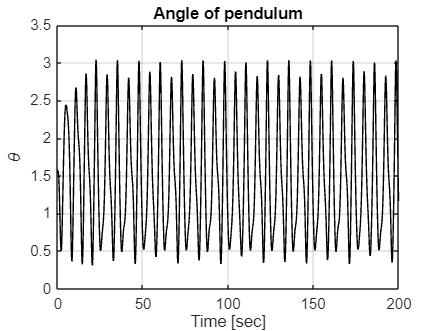


%% Run Simulation and save results
results = sim('Simulink_demo_2024.slx', 'StopTime', '200');

% Restructure q into 2 columns
results.q = squeeze(results.q)';

%% Plot the results
figure(1)
plot(results.tout,results.q(:,1),'k')
grid on
xlabel('Time [sec]')
ylabel('\theta')
title('Angle of pendulum')

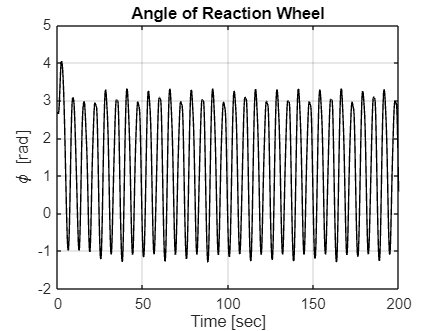


figure(2)
plot(results.tout,results.q(:,2)+1.12,'k')
grid on
xlabel('Time [sec]')
ylabel('\phi [rad]')
title('Angle of Reaction Wheel')

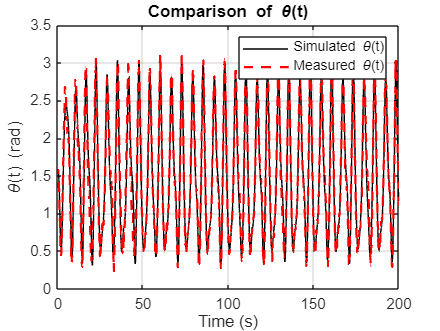

load('MeasuredSignals.mat');
plot(results.tout,results.q(:,1),'k')
hold on;
plot(MeasuredSignals.t, MeasuredSignals.theta, 'r--', 'LineWidth', 1.5);
title('Comparison of \theta(t)');
xlabel('Time (s)');
ylabel('\theta(t) (rad)');
grid on;
legend('Simulated \theta(t)', 'Measured \theta(t)');
hold off;

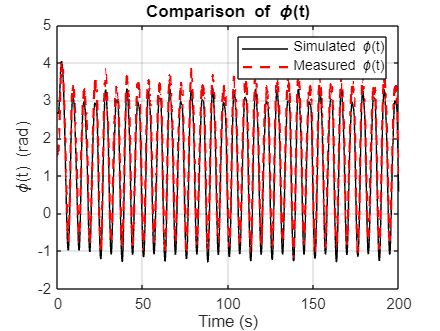


figure;
plot(results.tout,results.q(:,2)+1.12,'k')
hold on;
plot(MeasuredSignals.t, MeasuredSignals.varphi, 'r--', 'LineWidth', 1.5);  % Use MeasuredSignals.varphi
title('Comparison of \phi(t)');
xlabel('Time (s)');
ylabel('\phi(t) (rad)');
grid on;
legend('Simulated \phi(t)', 'Measured \phi(t)');
hold off;